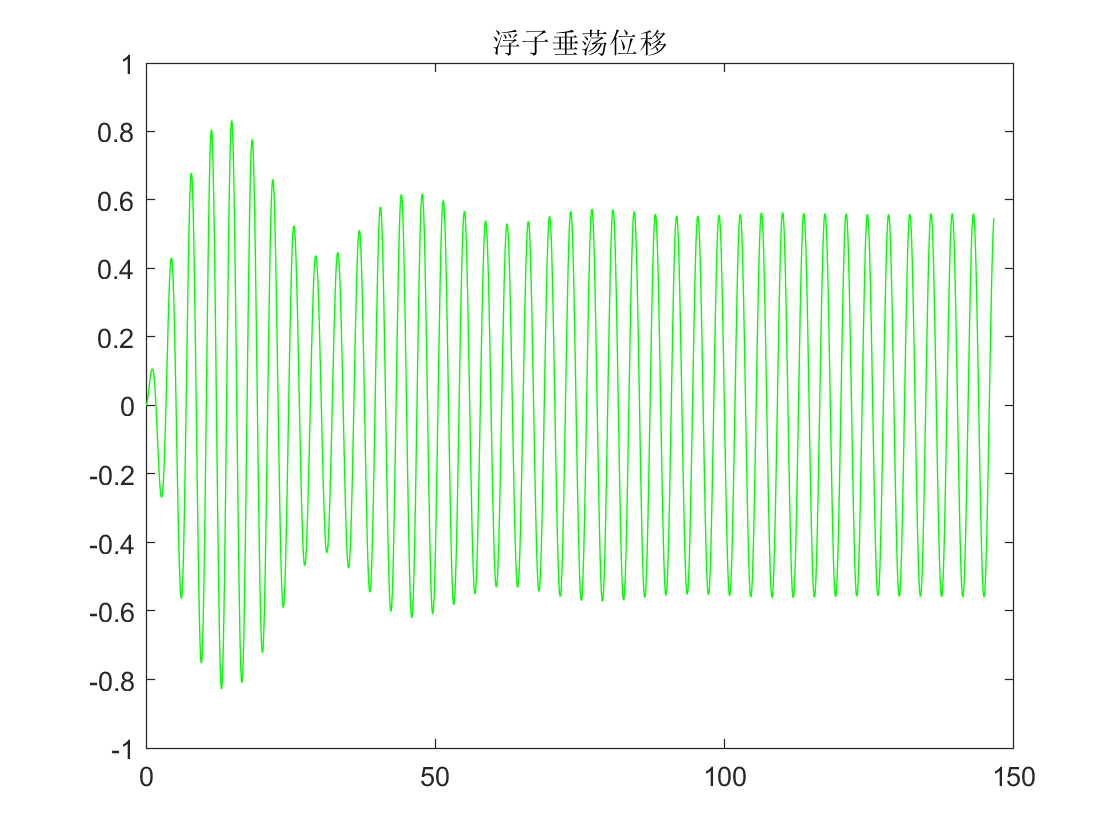

format long
%隔离法
V=(4866+2433)/1025; 
V1=1/3*pi*0.8; 
x0=-(V-V1)/pi+1.4;
z0=0.5-2433*9.8/80000;
b0=0;a0=0;
w=1.7152;
x1=0;z1=0;b1=0;a1=0;
[t,xb]=ode45(@(t,xb)odefun_q3_1(t,xb),[0:0.02:40*2*pi/w],[x0,b0,z0,a0,x1,b1,z1,a1]);%作图数据来源
[t1,xb1]=ode45(@(t,xb)odefun_q3_1(t,xb),[0:0.2:40*2*pi/w],[x0,b0,z0,a0,x1,b1,z1,a1]);%result3数据来源
[t2,xb2]=ode45(@(t,xb)odefun_q3_1(t,xb),[0:10:40*2*pi/w],[x0,b0,z0,a0,x1,b1,z1,a1]);%论文需要（间隔10s）数据来源
%xb(1)=x;xb(2)=beta;xb(3)=z;xb(4)=alpha;xb(5)=vx;xb(6)=vbeta;xb(7)=vz;xb(8)=valpha;
xb1(:,1)=xb1(:,1)-x0;
xb1(:,3)=xb1(:,3)-z0;
xb2(:,1)=xb2(:,1)-x0;
xb2(:,3)=xb2(:,3)-z0;

plot(t,xb(:,1)-x0,'g')%x浮子垂荡位移
title('浮子垂荡位移')

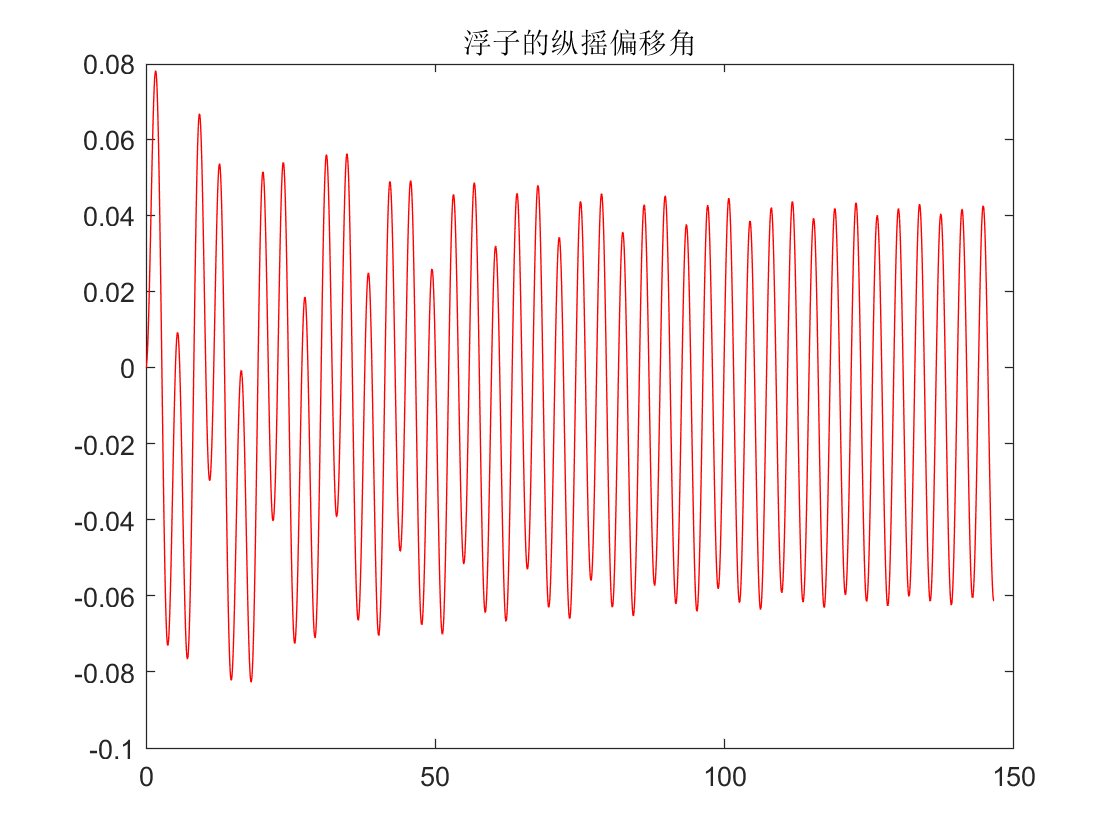

plot(t,xb(:,2),'r')%beta浮子的纵摇偏移角
title('浮子的纵摇偏移角')

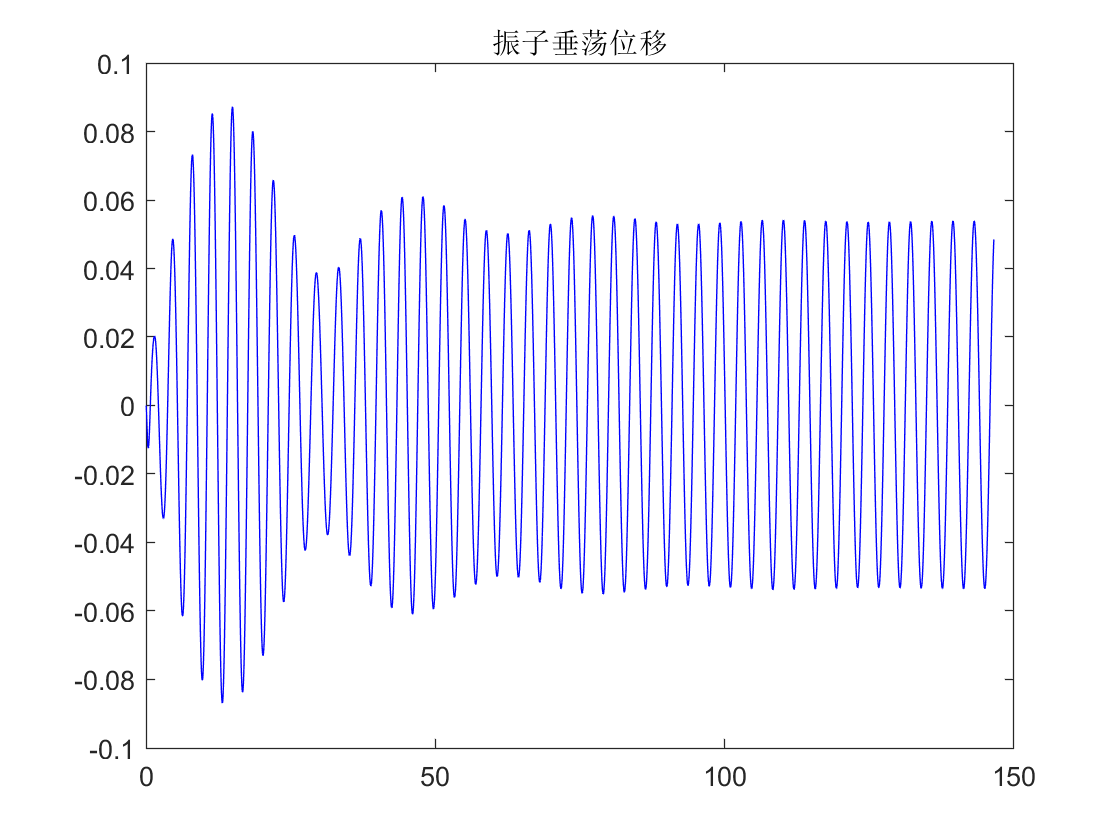

plot(t,xb(:,3)-z0,'b')%z振子垂荡位移
title('振子垂荡位移')

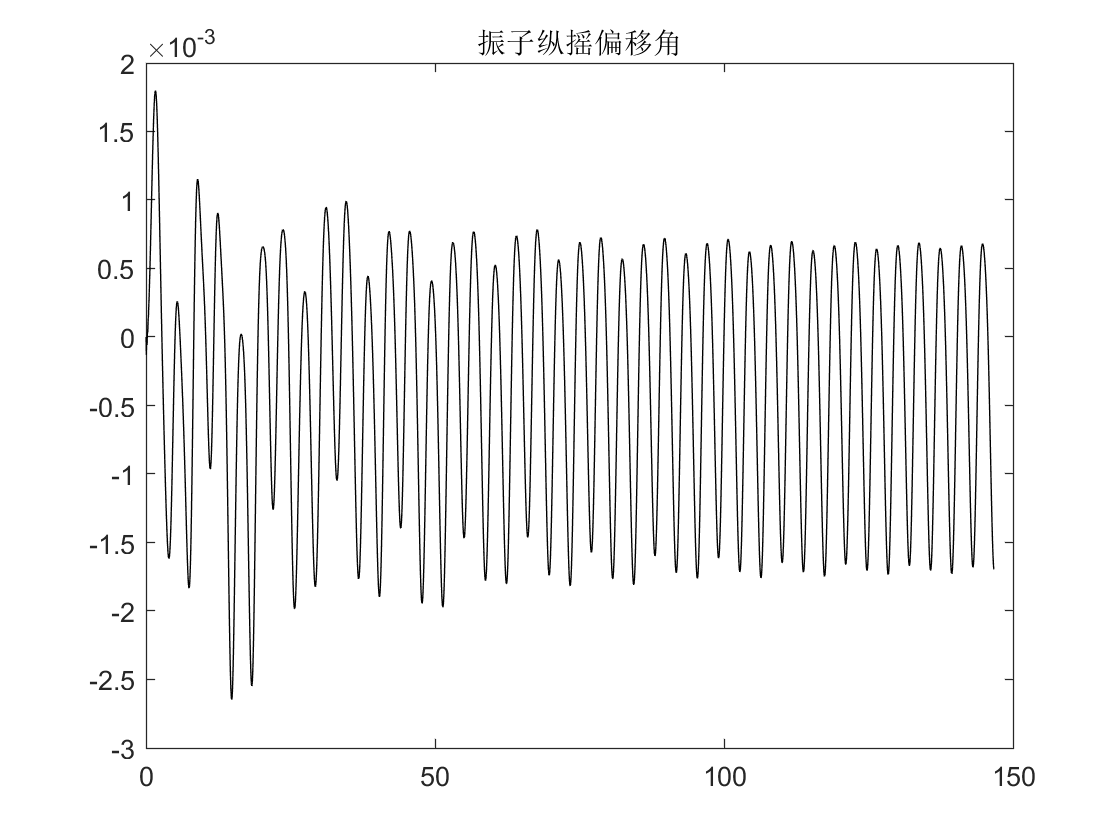

plot(t,xb(:,4),'k')%alphaz振子纵摇偏移角
title('振子纵摇偏移角')

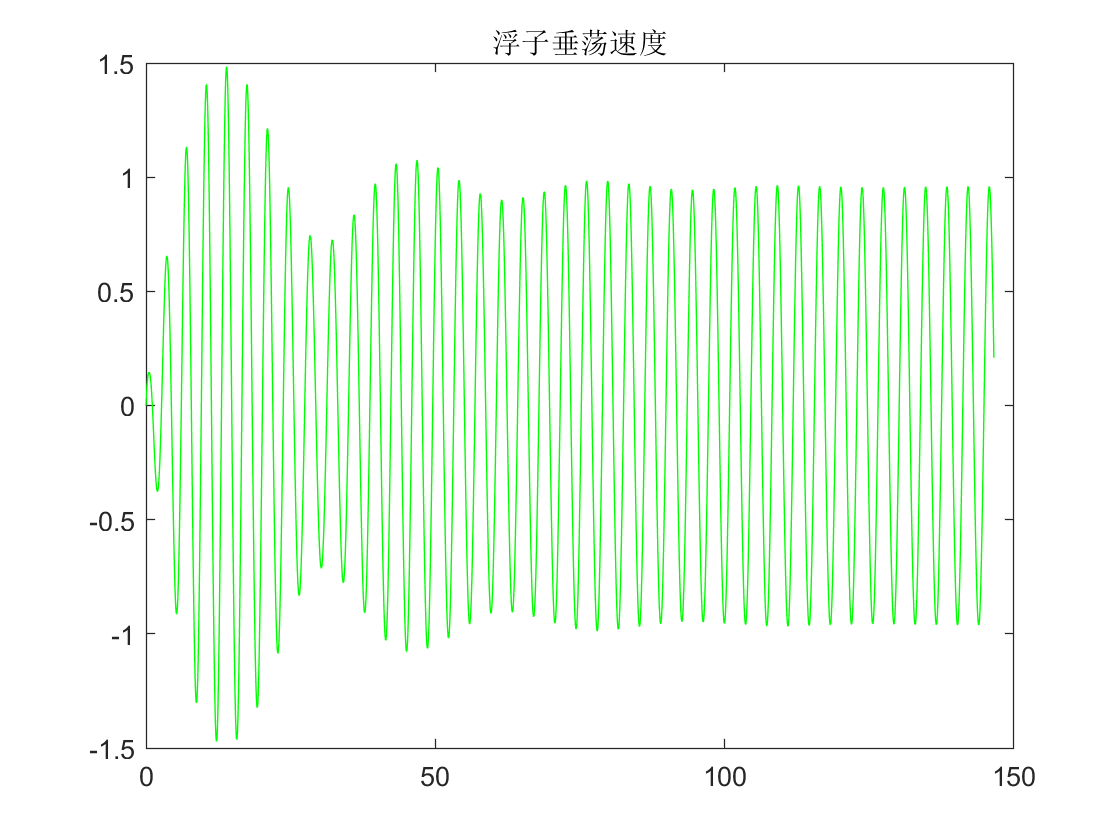

plot(t,xb(:,5),'g')%浮子垂荡速度
title('浮子垂荡速度')

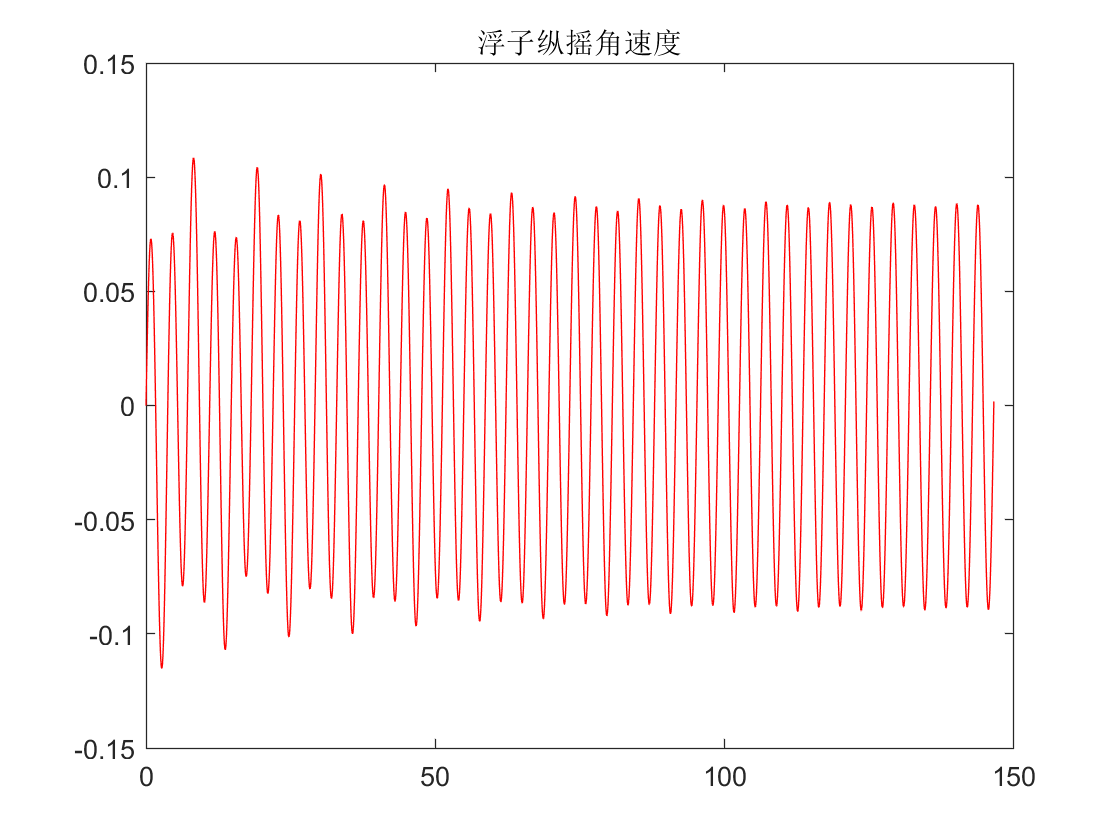

plot(t,xb(:,6),'r')%浮子纵摇角速度
title('浮子纵摇角速度')

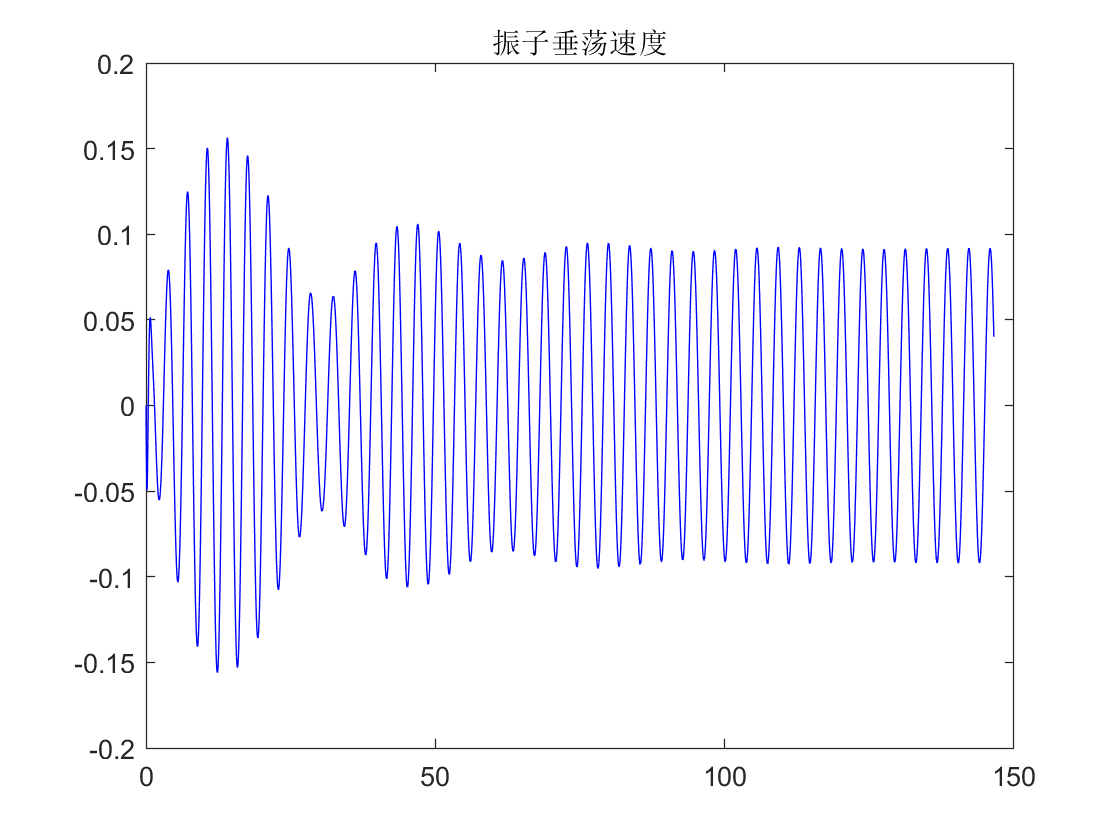

plot(t,xb(:,7),'b')%振子垂荡速度
title('振子垂荡速度')

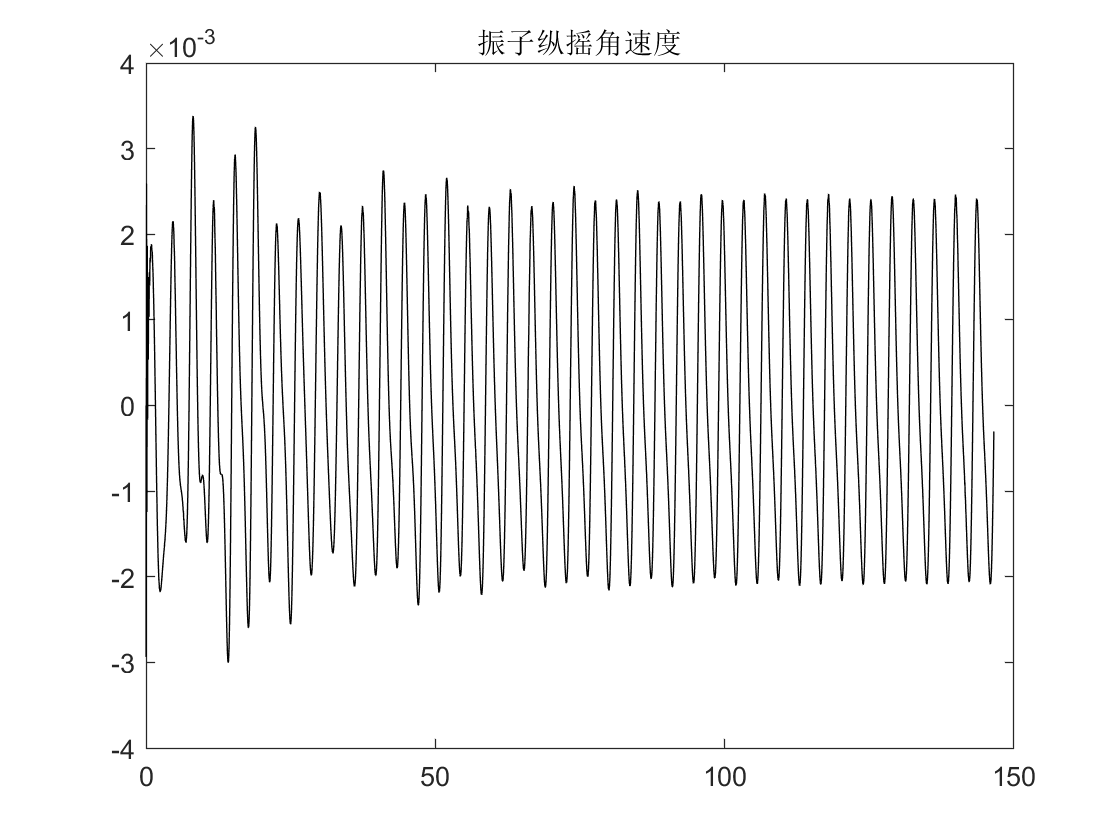

plot(t,xb(:,8),'k')%振子纵摇角速度
title('振子纵摇角速度')